# Lab 04

## Syed Muhammad Asad Ali

sa09475

**Task(1)(a)**

x = [2 2 4 5]

x =      2     2     4     5


y = [4 5 4 0]

y =      4     5     4     0


[r , k] = xcorr(x,y)

r =    -0.0000    8.0000   18.0000   34.0000   48.0000   41.0000   20.0000


k =     -3    -2    -1     0     1     2     3


The range of lags returned by the xcorr function is 7.

**(b)**

The length of the correlation output will be (n1+n2)-1.

**(c)**

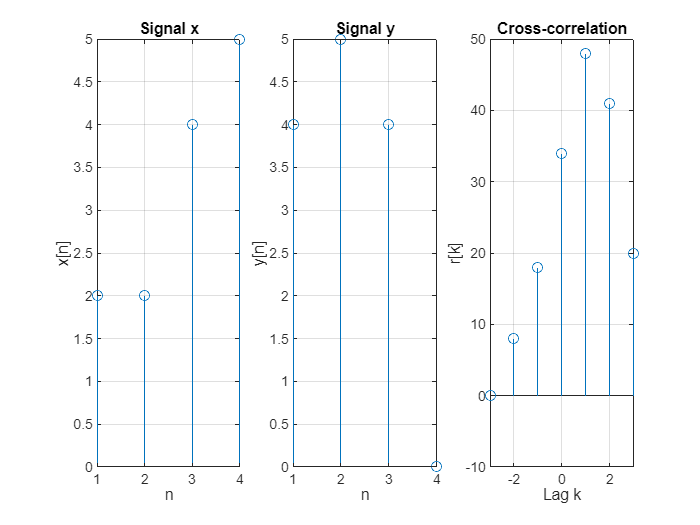

figure;

subplot(1,3,1);
stem(x)
xlabel('n');
ylabel('x[n]');
title('Signal x');
grid on;

subplot(1,3,2);
stem(y)
xlabel('n');
ylabel('y[n]');
title('Signal y');
grid on;

subplot(1,3,3);
stem(k,r)
xlabel('Lag k');
ylabel('r[k]');
title('Cross-correlation');
grid on;

**Task (2)**

x = [3 4 5 8]

x =      3     4     5     8


[r , k] = xcorr(x)

r =    24.0000   47.0000   72.0000  114.0000   72.0000   47.0000   24.0000


k =     -3    -2    -1     0     1     2     3


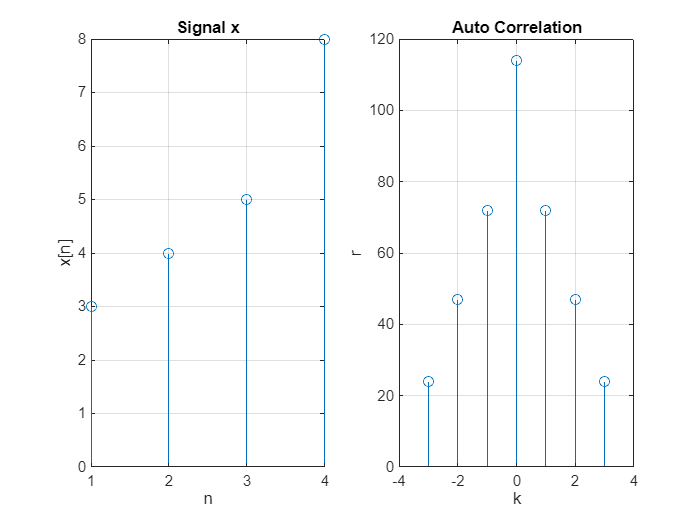


figure;
subplot(1,2,1);
stem(x);
xlabel('n')
ylabel('x[n]')
title('Signal x')
grid on;

subplot(1,2,2)
stem(k,r)
xlabel('k')
ylabel('r')
title('Auto Correlation')
grid on;

**Task (3)**

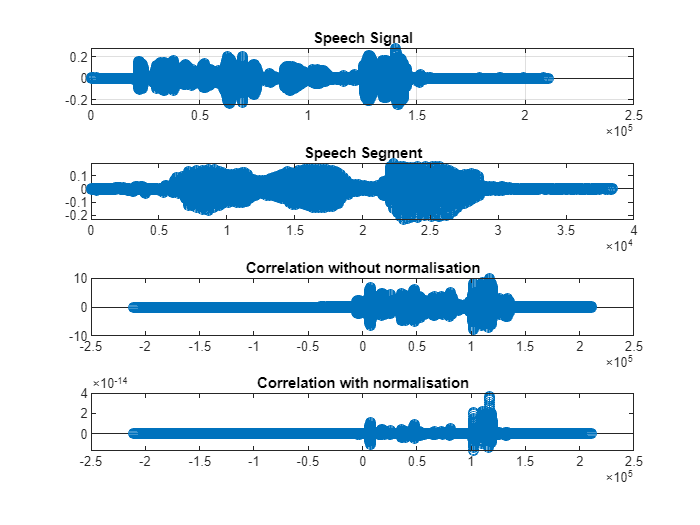

[y , Fs_y] = audioread('Speech_segment.wav'); % segment of signal we want to
%search
[x , Fs_x] = audioread('speech.wav');% complete signal or speech
sound(y , Fs_y) % sends the signal in vector y (with sample frequency Fs ̇y)
%to the speaker on PC
pause(2) %to insert a pause of 2 seconds between the two audio files
sound(x , Fs_x)
[correlation , lag] = xcorr(x,y); % Correlation is obtained
[~ , cmax] = max(abs(correlation)); % Finding maximum value
Nonlinear_Effect = (1.1* correlation/cmax).^3;
figure;
subplot(4,1,1);
stem(x);
title('Speech Signal')
grid on;

subplot(4,1,2);
stem(y);
title('Speech Segment');

subplot(4,1,3);
stem(lag,correlation);
title('Correlation without normalisation')

subplot(4,1,4)
stem(lag,Nonlinear_Effect)
title('Correlation with normalisation')

location = lag(cmax)

location = 116794

sound(x(location:end),Fs_x);

**Task (4)**

[x , Fs_x] = audioread('speech.wav');
[y , Fs_y] = audioread('Speech_segment.wav');

x_noise = randn(size(x))

x_noise =     0.4605
   -1.7914
    0.7353
   -0.7415
   -1.3414
   -0.3059
   -1.0180
   -0.3560
   -1.0275
    0.1780



x_new = x+x_noise/2;

sound(x_new , Fs_x);

[r ,  k] = xcorr(x_new , y)

r =          0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


k =      -210586     -210585     -210584     -210583     -210582     -210581     -210580     -210579     -210578     -210577     -210576     -210575     -210574     -210573     -210572     -210571     -210570     -210569     -210568     -210567     -210566     -210565     -210564     -210563     -210562     -210561     -210560     -210559     -210558     -210557     -210556     -210555     -210554     -210553     -210552     -210551     -210550     -210549     -210548     -210547     -210546     -210545     -210544     -210543     -210542     -210541     -210540     -210539     -210538     -210537


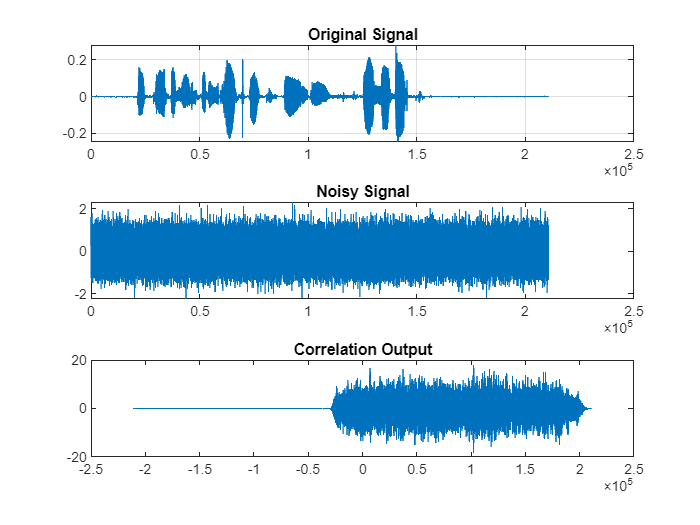


figure;
subplot(3,1,1);
plot(x);
title('Original Signal');
grid on;

subplot(3,1,2);
plot(x_new);
title('Noisy Signal');

subplot(3,1,3);
plot(k,r);
title('Correlation Output');


power_signal = (sum(x_new.^2)/length(x_new))

power_signal = 0.2505

power_noise = (sum(x_noise.^2)/length(x_noise))

power_noise = 0.9985

sound(x_new,Fs_x)
SNR = power_signal / power_noise

SNR = 0.2509

### Post Lab

#### **Task (5)**

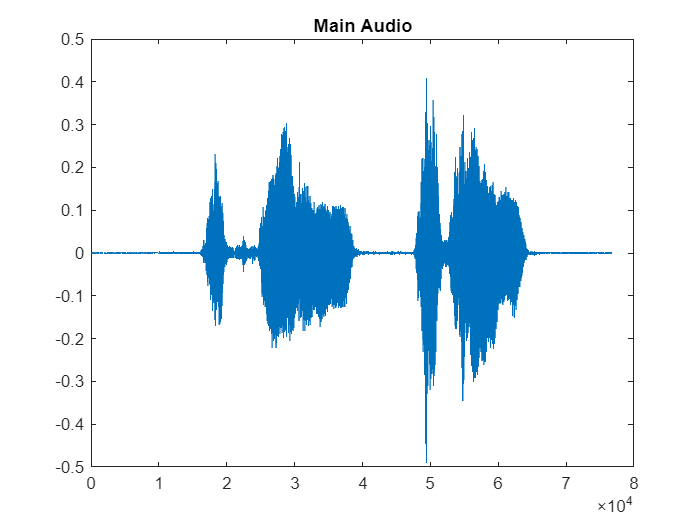

[x, Fs_x] = audioread('main_audio.wav');
[o1, Fs_o1] = audioread('okay_1.wav');
[o2, Fs_o2] = audioread('okay_2.wav');
[o3, Fs_o3] = audioread('okay_4.wav');
[o4, Fs_o4] = audioread('okay_1.wav');
pause(2)
sound(x, Fs_x)
pause(2)
sound(o1, Fs_o1)
pause(2)
sound(o2, Fs_o2)
pause(2)
sound(o3, Fs_o3)
pause(2)
sound(o4, Fs_o4)
[correlation1 , lag1] = xcorr(x,o1);
cmax1 = max(abs(correlation1));
Nonlinear_Effect1 = (1.1* correlation1/cmax1).^3 ;
[correlation2 , lag2] = xcorr(x,o2);
cmax2 = max(abs(correlation2));
Nonlinear_Effect2 = (1.1* correlation2/cmax2).^3 ;
[correlation3 , lag3] = xcorr(x,o3);
cmax3 = max(abs(correlation3));
Nonlinear_Effect3 = (1.1* correlation3/cmax3).^3 ;
[correlation4 , lag4] = xcorr(x,o4);
cmax4 = max(abs(correlation4));
Nonlinear_Effect4 = (1.1* correlation4/cmax4).^3 ;
figure; plot(x);
title ("Main Audio");

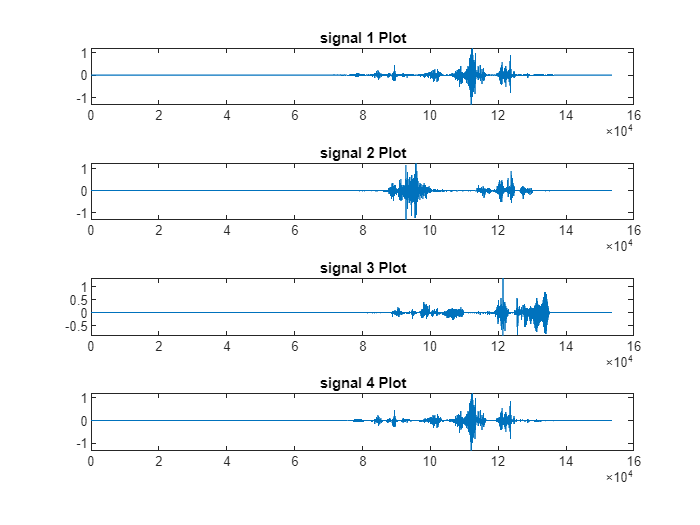

figure;
subplot 411; plot(Nonlinear_Effect1);
title ("signal 1 Plot");
subplot 412; plot(Nonlinear_Effect2);
title ("signal 2 Plot");
subplot 413; plot(Nonlinear_Effect3);
title ("signal 3 Plot");
subplot 414; plot(Nonlinear_Effect4);
title ("signal 4 Plot");

threshold = min([cmax1 cmax2 cmax3 cmax4])

threshold = 2.3188

if (cmax1 > threshold)
 disp("Signal 1: phrase detected");
else
 disp("Signal 1: phrase not detected");
end

Signal 1: phrase detected


if (cmax2 > threshold)
 disp("Signal 2: phrase detected");
else
 disp("Signal 2: phrase not detected");
end

Signal 2: phrase detected


if (cmax3 > threshold)
 disp("Signal 3: phrase detected");
else
 disp("Signal 3: phrase not detected");
end

Signal 3: phrase not detected


if (cmax4 > threshold)
 disp("Signal 4: phrase detected");
else
 disp("Signal 4: phrase not detected");
end

Signal 4: phrase detected


**Observation**:  The threshold is the lowest value of the correlation peaks of all the samples that are provided. As a result, any sound that is provided as input can be used to identify the "Okay" sound. This is not the best audio detector because it only has data from the four provided samples, making it difficult for it to detect any further samples. Its processing time will also increase as the dataset grows